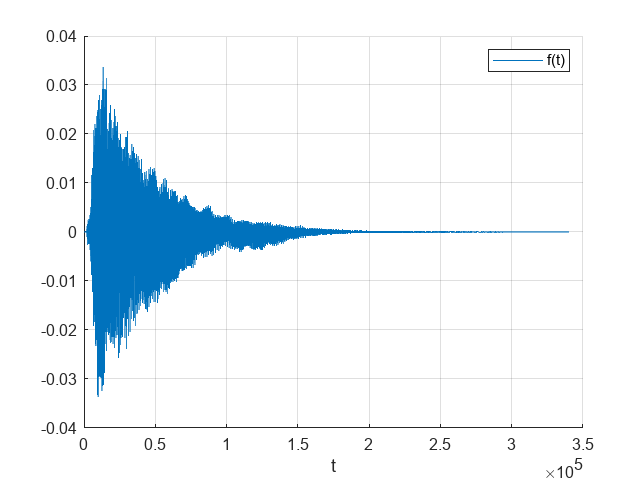

aud = audioread('Аккорд (3).mp3');
aud = aud(:,1);
f = figure;
hold on
grid on
plot(aud)
xlabel('t')
legend('f(t)')
% saveas(f,'C:\LATEX\Fourier_analiz\Fourier_2\music_1.png');

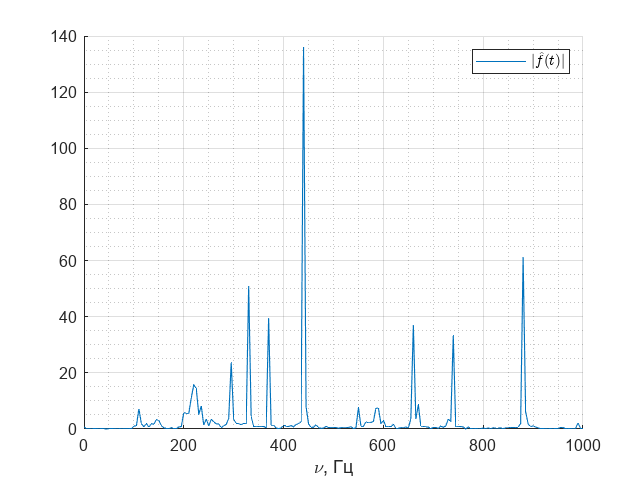


F = 44100;
T = (length(aud)-1)/F;
t = 0:1/F:T; t = t.';

dv = 5;
v = 0 : dv : 1000;
Y = zeros(1,length(v));
for k = 1 : length(v)
    Y(k) = trapz(aud.*exp(-1i*2*pi*v(k)*t)); % Преобразование Фурье
end

plott = sqrt(real(Y).^2+imag(Y).^2);
f1 = figure;
hold on
grid on
grid minor
plot(v, plott)
xlabel('\nu, Гц')
legend('$|\hat f(t)|$','Interpreter','latex')

% saveas(f1,'C:\LATEX\Fourier_analiz\Fourier_2\music_2.png');